# Vectorizing vector products

This scripts tests how to vectorize the operation of vector multiplication. I found myself needing this becuase Matlab defaults to the proper approach of matrix multiplication as in the following operation

$\mathbf{x} = \mathbf{Ab}$

Where $\mathbf{x} \in \mathbb{R}^n$, $\mathbf{A} \in \mathbb{R}^{n \times m}$, and $\mathbf{b} \in \mathbb{R}^m$. 

But what I needed is


$$\mathbf{X} = \mathbf{AB}$$
 

Where $\mathbf{X} = \left[\matrix{\mathbf{x}_1 ~ \mathbf{x}_2 ~ \mathbf{x}_3 \cdot \cdot \cdot \mathbf{x}_k}\right]$, $\mathbf{B} = \left[\matrix{\mathbf{b}_1 ~ \mathbf{b}_2 ~ \mathbf{b}_3 \cdot \cdot \cdot \mathbf{b}_k}\right]$, and $\mathbf{x}, \mathbf{b} \in \mathbb{R}^n$, and $\mathbf{A} \in \mathbb{R}^{n \times n}$

The original implementation of the solution that did not vectorize the operation was

g = @(x,B) exp((-1/2)* (x'*B*x));

The problem with this form is that if x was an array of n column vectors (position vectors [x0 y0 z0]', then the product (x'*B*x) would produce an nxn matrix. Which is not the desired output. The desired output is an a scalar value the correspond to the result of the operation v'Bv if v was a single position vector. The solution was to use the function product as shown below.

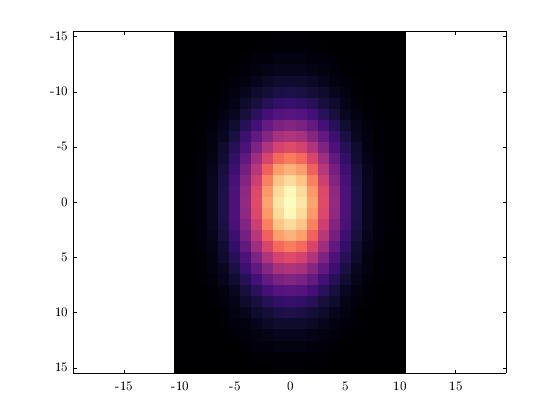

close all; clc; clearvars;

X = -10:10;
Y = -15:15;
[x, y] = meshgrid(X,Y);
g  = @(x,B) (exp((-1/2)*dot(x,B*x)));
s = [3 5];
B  = getB(s);

gApplied = g([x(:), y(:)]',B);
gApplied = reshape(gApplied,size(x));
figure
imagesc(X,Y,gApplied);
axis equal

function B = getB(s)
sdim = length(s);
if (sdim == 2) || (sdim == 3)  % 2d and 3d
    B = diag(1./s.^2);
else
    error('getHessianKernels_prototype::getB: something is wrong in fidning B');
end
end